clear
format shortG
warning off;
SetRNG(111);
% generate input data
%hierarchy 1 and 2 generation
k = 4;
dim = 100;
mu_range = [-1000 1000];
sigma = 100;
split_num = 2;
[center1,mu_mat] = subcluster_centroid(k,dim,split_num,mu_range,sigma); 
means = [];


%hierarchy 3 generation
center2 = [];  
for i = 1:size(center1,1)
    r = normrnd(0,20,[3,100])+center1(i,:);
    center2 = [center2;r];
end
center = center2;

% data generation with the given centroids
dim = 100;
num = 100;
sigma = 5;
[inputs,c] = subcluster_simulate(center,dim,num,sigma);
assign_id1 = repelem([1:4],600)';
assign_id2 = repelem([1:8],300)';
assign_id3 = repelem([1:24],100)';
true_label = assign_id3;

inputs = [inputs,assign_id1,assign_id2,assign_id3];
%inputs = inputs(randperm(size(inputs, 1)),:);
assign_id1 = inputs(:,end-2);
assign_id2 = inputs(:,end-1);
assign_id3 = inputs(:,end);
inputs = inputs(:,1:end-3);
data = inputs';

[idx,C,sumd,D] = kmeans(data',4);
[a,b] = groupcounts(idx);

true_label = assign_id3;
assigned_cluster = idx;
PTY1 = purity(assigned_cluster,true_label);
NMI1 = nmi(true_label, assigned_cluster);
[RI1, ARI1] = randindex(true_label, assigned_cluster);
[s1] = ClusterEvalSilhouette (data', assigned_cluster, 'cosine');
ch1 = ClusterEvalCalinskiHarabasz(data', assigned_cluster);
[db1] = ClusterEvalDaviesBouldin (data', assigned_cluster);

c2_DHC = {};
c2_assign = idx;
c1_center =  unique(idx);
for k2 = 1:length(c1_center);
    c1 = c1_center(k2);
    data_idx = find(idx == c1);
    K = 2;
    sub_data = data(:,data_idx)';
    [idx_2,C,sumd,D] = kmeans(sub_data,K);
    c2_assign(data_idx) = idx_2+k2*10;
    c2_DHC{k2} = [data_idx,idx_2+k2*10];
end
[a,b] = groupcounts(c2_assign);

true_label = assign_id3;
assigned_cluster = c2_assign;
PTY2 = purity(assigned_cluster,true_label);
NMI2 = nmi(true_label, assigned_cluster);
[RI2, ARI2] = randindex(true_label, assigned_cluster);
[s2] = ClusterEvalSilhouette (data', assigned_cluster, 'cosine');
ch2 = ClusterEvalCalinskiHarabasz(data', assigned_cluster);
[db2] = ClusterEvalDaviesBouldin (data', assigned_cluster);

c3_DHC = {};
c3_assign = [];
c2_center =  unique(c2_assign);
for k3 = 1:length(c2_center);
    c2 = c2_center(k3);
    data_idx = find(c2_assign == c2);
    K = 3;
    sub_data = data(:,data_idx)';
    [idx_3,C,sumd,D] = kmeans(sub_data,K);
    c3_assign(data_idx) = idx_3+k3*10;
    c3_DHC{k3} = [data_idx,idx_3+k3*10];
end
c3_assign = c3_assign';
[a,b] = groupcounts(c3_assign);

true_label = assign_id3;
assigned_cluster = c3_assign;
PTY3 = purity(assigned_cluster,true_label);
NMI3 = nmi(true_label, assigned_cluster);
[RI3, ARI3] = randindex(true_label, assigned_cluster);
[s3] = ClusterEvalSilhouette (data', assigned_cluster, 'cosine');
ch3 = ClusterEvalCalinskiHarabasz(data', assigned_cluster);
[db3] = ClusterEvalDaviesBouldin (data', assigned_cluster);

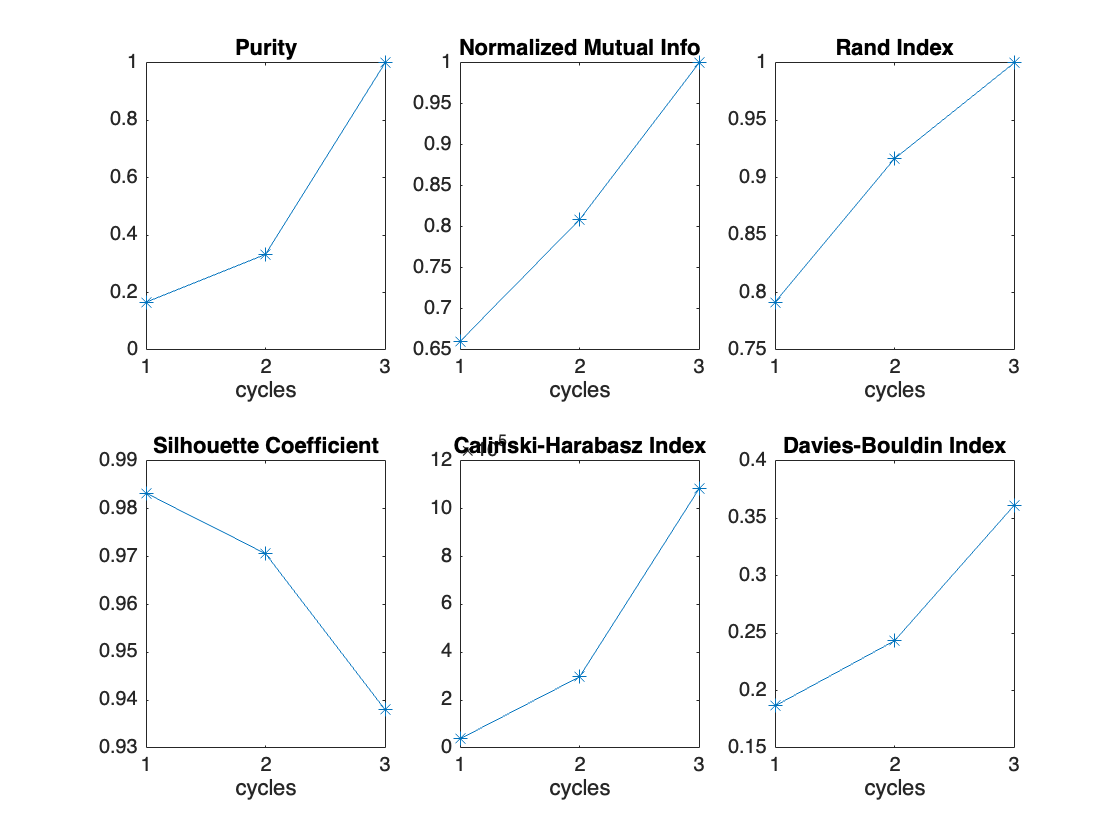

PTY = [PTY1; PTY2; PTY3];
NMI = [NMI1; NMI2; NMI3];
RI = [RI1; RI2; RI3];
s = [s1; s2; s3];
ch = [ch1; ch2; ch3];
db = [db1; db2; db3];


figure;
subplot(2,3,1)
plot(PTY,'-*')
title("Purity")
xlabel('cycles')
subplot(2,3,2)
plot(NMI,'-*')
title("Normalized Mutual Info")
xlabel('cycles')
subplot(2,3,3)
plot(RI,'-*')
title("Rand Index")
xlabel('cycles')
subplot(2,3,4)
plot(s,'-*')
title("Silhouette Coefficient")
xlabel('cycles')
subplot(2,3,5)
plot(ch,'-*')
title("Calinski-Harabasz Index")
xlabel('cycles')
subplot(2,3,6)
plot(db,'-*')
title("Davies-Bouldin Index")
xlabel('cycles')



% Create the table
T = table(PTY, NMI, RI, s, ch, db);

% Set row names
T.Properties.RowNames = {'cycle 1', 'cycle 2', 'cycle 3'};

% Display the table
disp(T);

                 PTY        NMI        RI          s           ch          db   
               _______    _______    _______    _______    __________    _______

    cycle 1    0.16667    0.66046    0.79158    0.98329         38139    0.18665
    cycle 2    0.33333     0.8089    0.91663    0.97063    2.9762e+05    0.24335
    cycle 3          1          1          1    0.93803    1.0834e+06    0.36124

